% Lagrange interpolation method
clf

T = [0 21.1 37.8 54.4 71.1 87.8 100];
mu = [1.79 1.13 0.696 0.519 0.338 0.321 0.296];

syms t;

Pl = @(t) 0;

for i = 1:length(mu)
    l = @(t) 1;

    for j = 1:length(mu)
        if (j ~= i)
            l = l * (t - T(j)) / (T(i) - T(j));
        end
    end

    vpa(l, 5)

    Pl = Pl + l * mu(i);
end

$$ans = 7.7901e-10\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)\,\left(0.047393\,t-1.0\right)$$

$$ans = -3.2388e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)$$

$$ans = 9.2147e-10\,t\,\left(t-71.1\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)$$

$$ans = -1.3074e-9\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)$$

$$ans = 1.0481e-9\,t\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)$$

$$ans = -5.0186e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-100.0\right)\,\left(t-54.4\right)$$

$$ans = 1.2674e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-54.4\right)$$

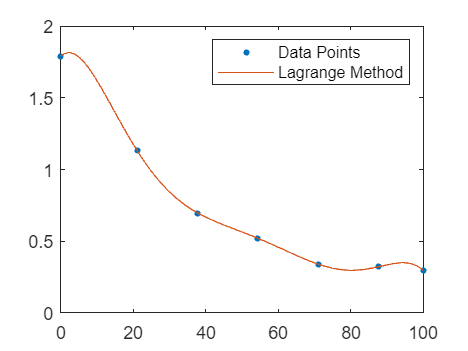


plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pl, [T(1) T(length(mu))]);

legend(["Data Points", "Lagrange Method"])


vpa(Pl, 5)

$$ans = 1.3944e-9\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)\,\left(0.047393\,t-1.0\right)-6.7856e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)+3.7515e-11\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-54.4\right)-1.611e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-100.0\right)\,\left(t-54.4\right)-3.6598e-10\,t\,\left(t-71.1\right)\,\left(t-37.8\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)+6.4134e-10\,t\,\left(t-71.1\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)+3.5424e-10\,t\,\left(t-37.8\right)\,\left(t-21.1\right)\,\left(t-87.8\right)\,\left(t-100.0\right)\,\left(t-54.4\right)$$

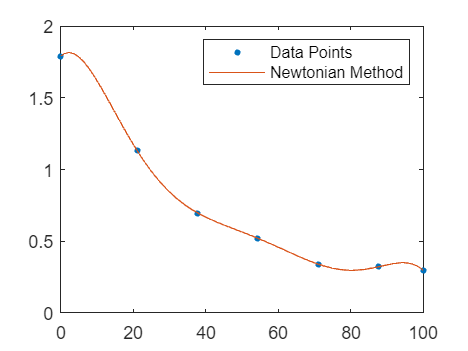

% Newton interpolation
clf

T = [0 21.1 37.8 54.4 71.1 87.8 100];
mu = [1.79 1.13 0.696 0.519 0.338 0.321 0.296];

syms t;

mus = [mu; zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu)); zeros(1, length(mu))];

for j = 2:length(mu)
    for i = j:length(mu)
        mus(j, i) = (mus(j - 1, i) - mus(j - 1, j - 1)) / (T(i) - T(j - 1));
    end
end

Pn = @(t) mus(length(mu), length(mu));

for i = (length(mu) - 1):-1:1
    Pn = mus(i, i) + (t - T(i)) * Pn;
end

plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pn, [T(1) T(length(mu))]);

legend(["Data Points", "Newtonian Method"])


vpa(mus', 5)

$$ans = \left(\begin{array}{ccccccc} 1.79 & 0 & 0 & 0 & 0 & 0 & 0\\ 1.13 & -0.03128 & 0 & 0 & 0 & 0 & 0\\ 0.696 & -0.028942 & 0.00013999 & 0 & 0 & 0 & 0\\ 0.519 & -0.023364 & 0.00023771 & 5.8866e-6 & 0 & 0 & 0\\ 0.338 & -0.020422 & 0.00021715 & 2.3172e-6 & -2.1373e-7 & 0 & 0\\ 0.321 & -0.016731 & 0.00021812 & 1.5626e-6 & -1.2946e-7 & 5.0462e-9 & 0\\ 0.296 & -0.01494 & 0.00020709 & 1.0788e-6 & -1.0543e-7 & 3.7474e-9 & -1.0646e-10 \end{array}\right)$$


vpa(Pn, 5)

$$ans = 1.79-1.0\,t\,\left(\left(t-21.1\right)\,\left(\left(t-37.8\right)\,\left(\left(t-54.4\right)\,\left(\left(t-71.1\right)\,\left(1.0646e-10\,t-1.4393e-8\right)+2.1373e-7\right)-5.8866e-6\right)-0.00013999\right)+0.03128\right)$$

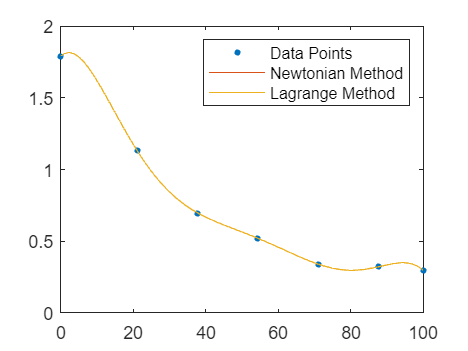

clf

plot(T, mu, '.', "MarkerSize", 10);
hold on

fplot(Pn, [T(1) T(length(mu))]);
fplot(Pl, [T(1) T(length(mu))]);

legend(["Data Points", "Newtonian Method", "Lagrange Method"])


Plagrange = matlabFunction(vpa(Pl, 5));
Pnewton = matlabFunction(vpa(Pn, 5));

fprintf("Lagrange for T = 10: %g", Plagrange(10));

Lagrange for T = 10: 1.62069

fprintf("Lagrange for T = 60: %g", Plagrange(60));

Lagrange for T = 60: 0.457169

fprintf("Newton for T = 10: %g", Pnewton(10));

Newton for T = 10: 1.62069

fprintf("Newton for T = 60: %g", Pnewton(60));

Newton for T = 60: 0.457169